1a. $x(n) = {1, 1, 1, 1, 1}$ and $h(n) = {1, 1, 1}$. find convolution of $y(n) = x(n)\star h(n)$

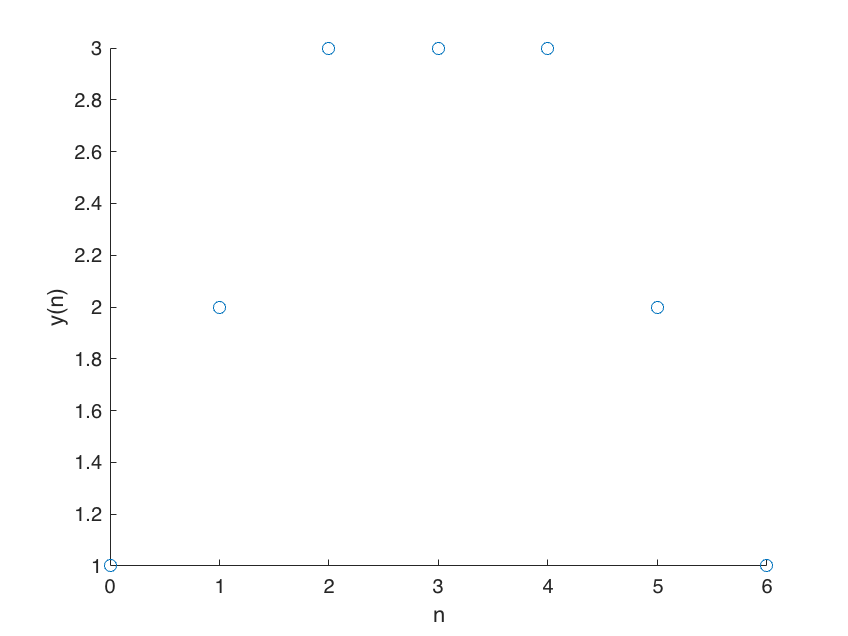

x = ones(5, 1);
h = ones(3, 1);
y = conv(x, h);
scatter(0:size(y)-1, y)
xlabel('n')
ylabel('y(n)')

1b. solving it by hand, we have $x(n) = u(n) - u(n - 5)$ and $h(n) = u(n) - u(n - 3)$. 

Taking the convolution we get $x(n) \star h(n) = \sum_{k = -\infty}^{\infty}[u(k) - u(k - 5)]\cdot[u(n - k) - u(n - 3 - k)]$


$$= \sum_{k = 0}^{\infty}[u(n - k) - u(n - 3 - k)] + \sum_{k = 5}^{\infty}[- u(n - k) + u(n - 3 - k)]$$


= $\sum_{k = 0}^{n}[1] - \sum_{k = 0}^{n - 3}[1] + \sum_{k = 5}^{n}[-1] + \sum_{k = 5}^{n - 3}[1]$

= $0$ for $n < 0$, 

$n+1$ for $0\le n \le 2$, 

$3$ for $2\le n \le 4$, 

$7 - n$ for $4\le n \le 6$, 

and $0$ for $n\ge 7$

we end up with 0, 1, 2, 3, 3, 2, 1, 0 for $y$ which does match up with the graph!

1c. the duration of $y(n)$ is $7$, or the sum of the durations of $x$ and $h$ minus 1. $x$ and $h$ start at 0, so $y$ will start at $0$ therefore ending at $6$.

1d. with new values of $x$ and $h$ find $y$

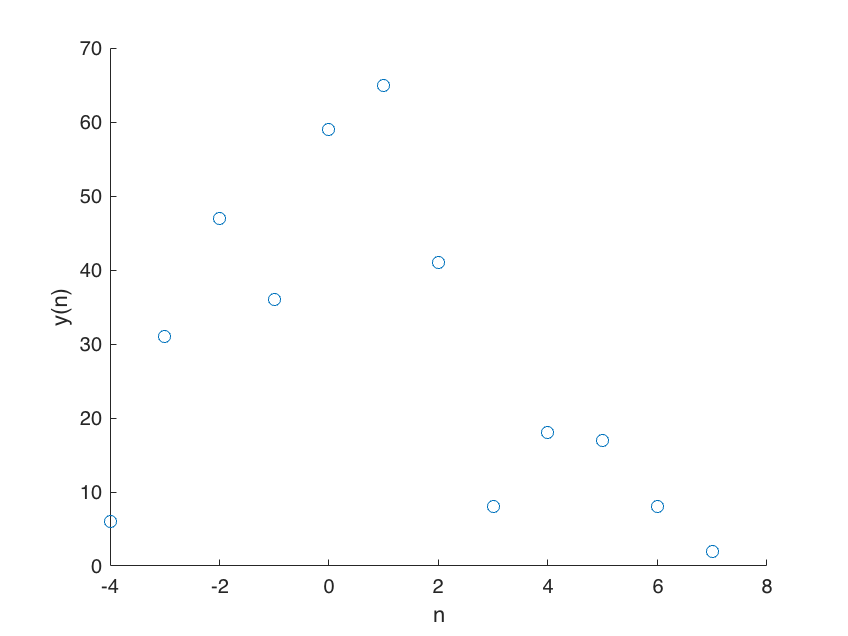

x = [3, 11, 7, 0, -1, 4, 2];
h = [2, 3, 0, 5, 2, 1];
y = conv(x, h);
scatter(-3-1:-3-1+length(y)-1, y)
xlabel('n')
ylabel('y(n)')